# Taller 1

## Punto 1

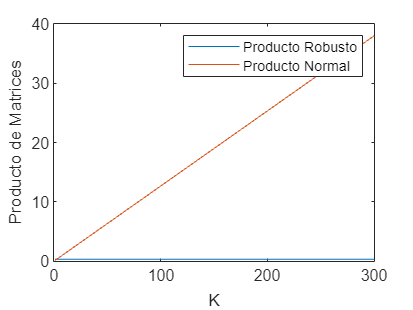

k=0;
A = [1,2,3;3,4,5;4,5,6];
B = [4,3;2,1;3,1+k];
%A*B
% Producto Robusto
x = 1:300;
y1 = zeros(1,300);
y2 = zeros(1,300);
C = A*B;
%C_mod = robust_product(A,B_mod)

C_original = robust_product(A,B);
for k = x
    B_mod = [4,3;2,1;3,1+k];
    C_mod = robust_product(A,B_mod);

    D_og = C - A*B_mod;
    D_robust = C_original-C_mod;
    y1(1,k) = norm(D_robust,"fro")/norm(C_original,"fro");
    y2(1,k) = norm(D_og,"fro")/norm(C,"fro");
end

plot(x,y1)
hold on
plot(x,y2)
legend('Producto Robusto', 'Producto Normal')
xlabel('K')
ylabel('Producto de Matrices')
hold off

## Punto 6

C_medifis = cov(medifis);
CI_medifis = inv(C_medifis);
d1_medifis = diag(C_medifis);
d2_medifis = diag(CI_medifis);
R_medifis = 1 - 1./(d1_medifis.*d2_medifis)

R_medifis =     0.7713
    0.9334
    0.8197
    0.9217
    0.8613
    0.8199
    0.5434
    0.7933




% Indicador R datos originales
C_data10 = cov(data10);
CI_data10 = inv(C_data10);
d1_data10 = diag(C_data10);
d2_data10 = diag(CI_data10);
R_data10 = 1 - 1./(d1_data10.*d2_data10)

R_data10 =     0.8377
    0.7342
    0.9123
    0.5432
    0.7830
    0.5717
    0.8226
    0.6763
    0.5760
    0.8576



% Indicador R datos originales
C_data12 = cov(data12);
CI_data12 = inv(C_data12);
d1_data12 = diag(C_data12);
d2_data12 = diag(CI_data12);
R_data12 = 1 - 1./(d1_data12.*d2_data12)

R_data12 =     0.8399
    0.7377
    0.9276
    0.5478
    0.8347
    0.7884
    0.5721
    0.6116
    0.8243
    0.6887


## Punto 10

a)

C = cov(data5);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
R = 1 - 1./(d1.*d2)

R =     0.8339
    0.8398
    0.7157
    0.6290
    0.8403



% Distancia Euclidea
d_Euclidea = pdist2(data5,mean(data5))

d_Euclidea =     5.0378
    5.3722
    1.9638
    7.9250
    5.8554
    4.1865
    4.6764
    7.4373
    3.6590
    3.6912


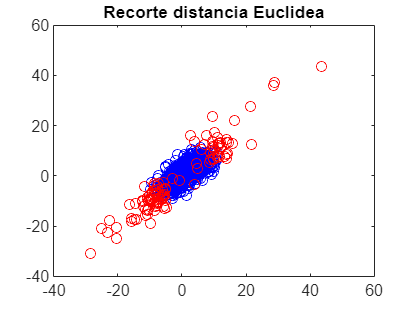

% d2 = sqrt(sum((data-mean(data)).^2,2))
pc_euclidea = prctile(d_Euclidea,90);
I_euclidea = find(d_Euclidea>pc_euclidea);
plot(data5(:,1),data5(:,2), 'ob')
hold on;
plot(data5(I_euclidea,1),data5(I_euclidea,2),'or')
title('Recorte distancia Euclidea')
hold off;

%Indicador R datos recortados Euclidea
datafiltrado = data5;
datafiltrado(I_euclidea,:) = [];
C = cov(datafiltrado);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
Rfiltrado = 1 - 1./(d1.*d2)

Rfiltrado =     0.7018
    0.6991
    0.5549
    0.4368
    0.7348


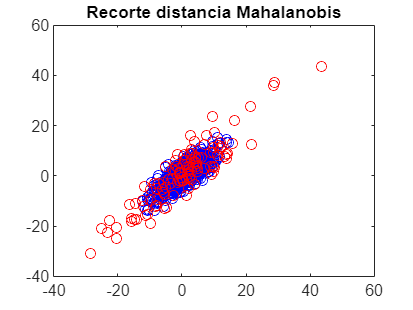


% Distancia de Mahalanobis
D = mahal(data5,data5);
plot(data5(:,1),data5(:,2), 'ob')
hold on;
pc = prctile(D,90);
I = find(D>pc);
plot(data5(I,1),data5(I,2),'or')
title('Recorte distancia Mahalanobis')
hold off;

%Indicador R datos recortados Mahalanobis
datafiltrado = data5;
datafiltrado(I,:) = [];
C = cov(datafiltrado);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
Rfiltrado = 1 - 1./(d1.*d2)

Rfiltrado =     0.8136
    0.8032
    0.7401
    0.5845
    0.8384


b)

%Spearman
spearman = corr(data5, 'type', 'Spearman')

spearman =     1.0000    0.8149    0.8000    0.7193    0.8487
    0.8149    1.0000    0.7847    0.6864    0.8607
    0.8000    0.7847    1.0000    0.6872    0.7857
    0.7193    0.6864    0.6872    1.0000    0.6905
    0.8487    0.8607    0.7857    0.6905    1.0000


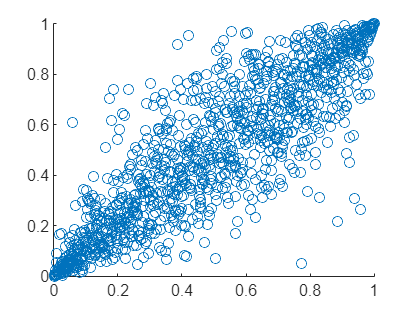

for i = 1:length(spearman)
    spearman(i,i) = 0;
end
maximo = max(spearman,[],"all");
[a, b] = find(spearman == maximo,1);

x = data5(:,a);
y = data5(:,b);
scatter(empiric(x),empiric(y))

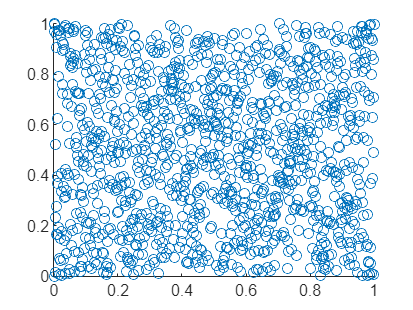


%Max-Min variabilidad
data_min = [x,y];
C = cov(data_min);
[vector, valor] = eig(C);
proyeccion_max = data_min*vector(:,end);
proyeccion_min = data_min*vector(:,1);
scatter(empiric(proyeccion_max),empiric(proyeccion_min))

var(proyeccion_max);

## Punto 11

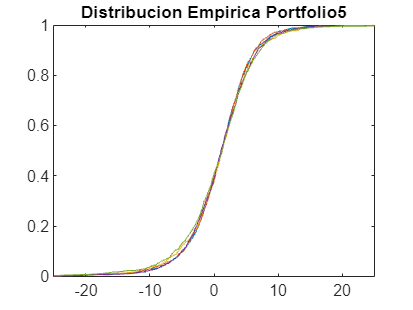

for i = 1:5
    plot(sort(data5(:,i)),sort(empiric(data5(:,i))))
    hold on
end
title('Distribucion Empirica Portfolio5')
xlim([-25,25])
hold off

## Punto 14

[~,cols] = size(data5)

cols = 5

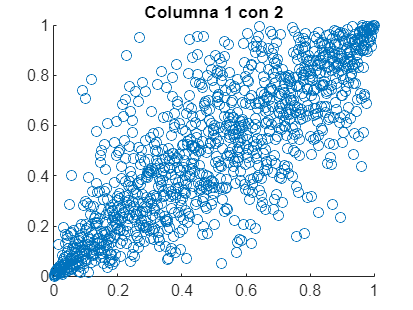


scatter(empiric(data5(:,1)),empiric(data5(:,2)))
title('Columna 1 con 2')

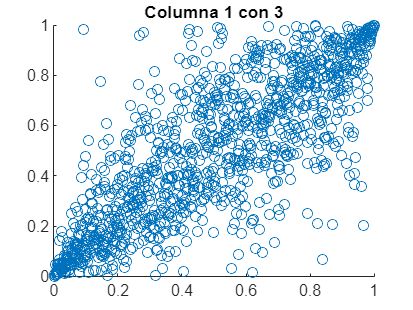

scatter(empiric(data5(:,1)),empiric(data5(:,3)))
title('Columna 1 con 3')

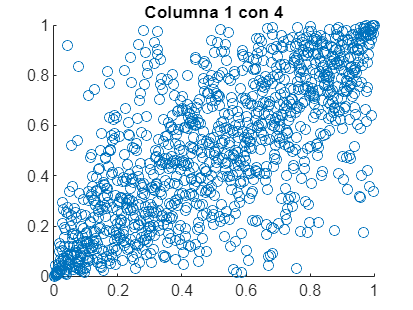

scatter(empiric(data5(:,1)),empiric(data5(:,4)))
title('Columna 1 con 4')

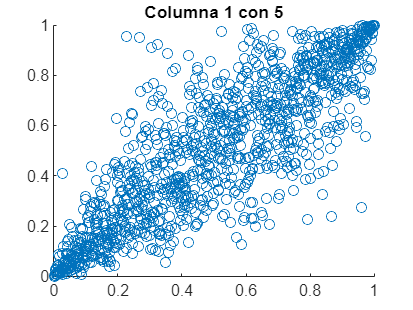

scatter(empiric(data5(:,1)),empiric(data5(:,5)))
title('Columna 1 con 5')

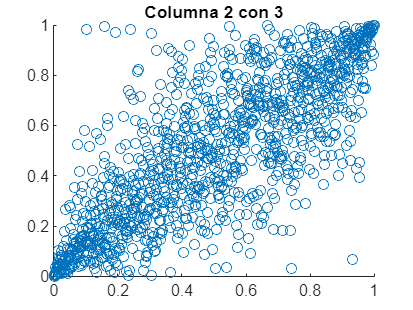

scatter(empiric(data5(:,2)),empiric(data5(:,3)))
title('Columna 2 con 3')

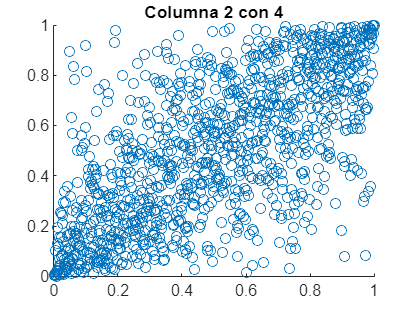

scatter(empiric(data5(:,2)),empiric(data5(:,4)))
title('Columna 2 con 4')

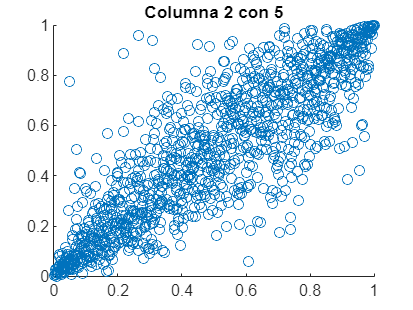

scatter(empiric(data5(:,2)),empiric(data5(:,5)))
title('Columna 2 con 5')

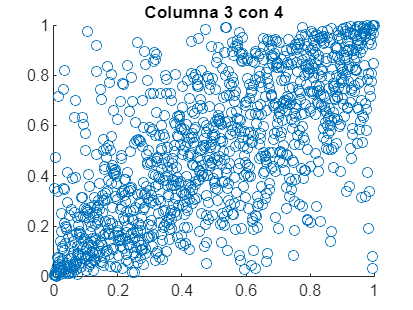

scatter(empiric(data5(:,3)),empiric(data5(:,4)))
title('Columna 3 con 4')

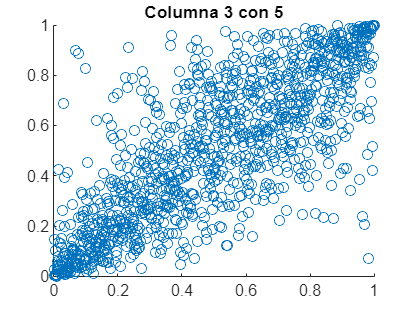

scatter(empiric(data5(:,3)),empiric(data5(:,5)))
title('Columna 3 con 5')

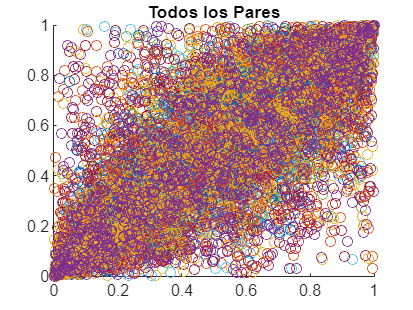

scatter(empiric(data5(:,4)),empiric(data5(:,5)))
title('Columna 4 con 5')


hold on
scatter(empiric(data5(:,1)),empiric(data5(:,2)))
scatter(empiric(data5(:,1)),empiric(data5(:,3)))
scatter(empiric(data5(:,1)),empiric(data5(:,4)))
scatter(empiric(data5(:,1)),empiric(data5(:,5)))
scatter(empiric(data5(:,2)),empiric(data5(:,3)))
scatter(empiric(data5(:,2)),empiric(data5(:,4)))
scatter(empiric(data5(:,2)),empiric(data5(:,5)))
scatter(empiric(data5(:,3)),empiric(data5(:,4)))
scatter(empiric(data5(:,3)),empiric(data5(:,5)))
scatter(empiric(data5(:,4)),empiric(data5(:,5)))
title('Todos los Pares')
hold off

## Punto 15

% Distancia Euclidea data5
d_Euclidea = pdist2(data5,mean(data5))

d_Euclidea =     5.0378
    5.3722
    1.9638
    7.9250
    5.8554
    4.1865
    4.6764
    7.4373
    3.6590
    3.6912


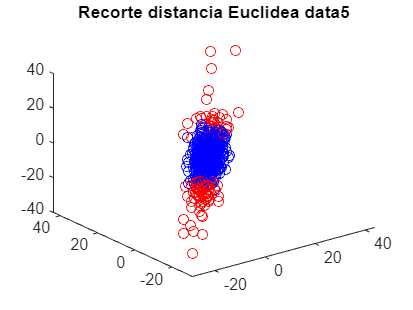

pc_euclidea = prctile(d_Euclidea,90);
I_euclidea = find(d_Euclidea>pc_euclidea);
plot3(data5(:,1),data5(:,2),data5(:,3),'ob')
hold on;
plot3(data5(I_euclidea,1),data5(I_euclidea,2),data5(I_euclidea,3),'or')
title('Recorte distancia Euclidea data5')
hold off;

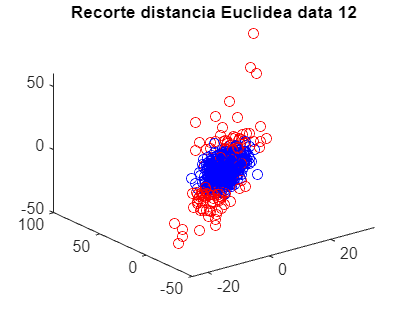


% Distancia Euclidea data12
d_Euclidea = pdist2(data12,mean(data12));
pc_euclidea = prctile(d_Euclidea,90);
I_euclidea = find(d_Euclidea>pc_euclidea);
plot3(data12(:,1),data12(:,2),data12(:,3),'ob')
hold on;
plot3(data12(I_euclidea,1),data12(I_euclidea,2),data12(I_euclidea,3),'or')
title('Recorte distancia Euclidea data 12')
hold off;

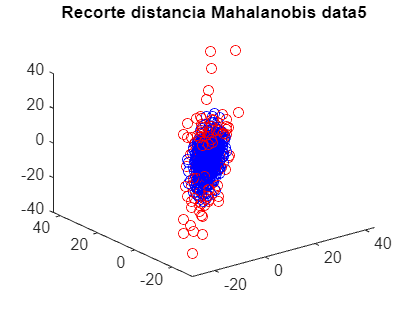


% Distancia de Mahalanobis data5
D = mahal(data5,data5);
plot3(data5(:,1),data5(:,2),data5(:,3), 'ob')
hold on;
pc = prctile(D,90);
I = find(D>pc);
plot3(data5(I,1),data5(I,2),data5(I,3),'or')
title('Recorte distancia Mahalanobis data5')
hold off;

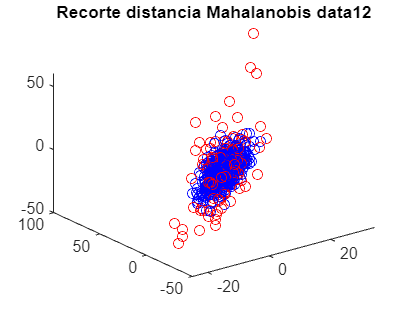


% Distancia de Mahalanobis data12
D = mahal(data12,data12);
plot3(data12(:,1),data12(:,2),data12(:,3), 'ob')
hold on;
pc = prctile(D,90);
I = find(D>pc);
plot3(data12(I,1),data12(I,2),data12(I,3),'or')
title('Recorte distancia Mahalanobis data12')
hold off;

## Punto 18

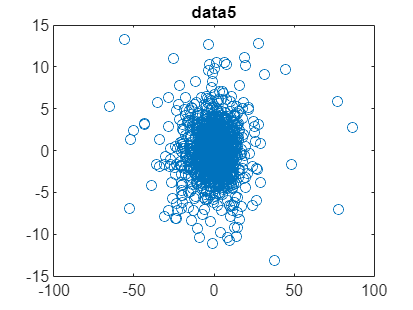

mean5 = mean(data5);
c5 = data5 - mean5;
cov5 = cov(c5);
[vector5, valor5] = eig(cov5);
[~,idx] = sort(diag(valor5),'descend');
v1 = vector5(:,idx(1));
v2 = vector5(:,idx(2));
pro2 = c5*[v1,v2];
plot(pro2(:,1),pro2(:,2),"o")
title("data5")

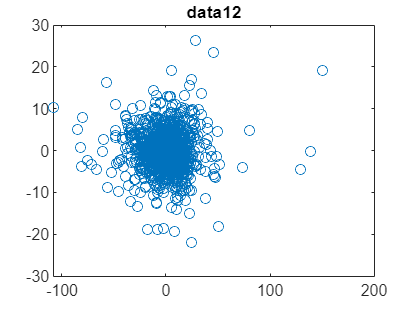


mean12 = mean(data12);
c12 = data12 - mean12;
cov12 = cov(c12);
[vector12, valor12] = eig(cov12);
[~,idx] = sort(diag(valor12),'descend');
v1 = vector12(:,idx(1));
v2 = vector12(:,idx(2));
pro2 = c12*[v1,v2];
plot(pro2(:,1),pro2(:,2),"o")
title("data12")

## Punto 21

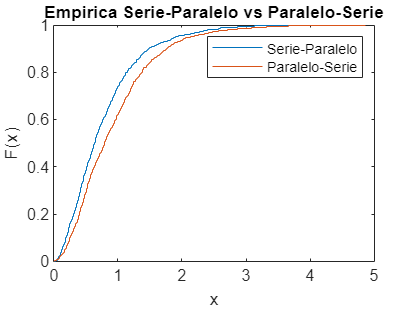

sistema = exprnd(1,1000,4);
col1 = sistema(:,1);
col2 = sistema(:,2);
col3 = sistema(:,3);
col4 = sistema(:,4);
serieparalelo = max(min(col1,col2),min(col3,col4));
paraleloserie = min(max(col1,col2),max(col3,col4));
ecdf(serieparalelo)
hold on
ecdf(paraleloserie)
title('Empirica Serie-Paralelo vs Paralelo-Serie')
legend('Serie-Paralelo', 'Paralelo-Serie')
hold off

## Punto 22

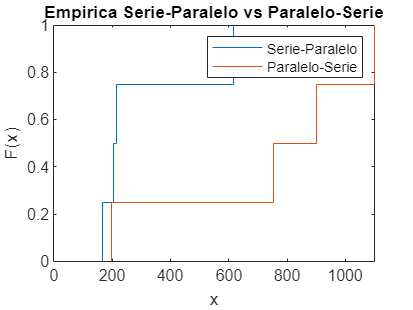

sistema2 = gamrnd(1,1000,4);
col1 = sistema2(:,1);
col2 = sistema2(:,2);
col3 = sistema2(:,3);
col4 = sistema2(:,4);
serieparalelo = max(min(col1,col2),min(col3,col4));
paraleloserie = min(max(col1,col2),max(col3,col4));
ecdf(serieparalelo)
hold on
ecdf(paraleloserie)
title('Empirica Serie-Paralelo vs Paralelo-Serie')
legend('Serie-Paralelo', 'Paralelo-Serie')
hold off

## Punto 24

sistema1 = exprnd(1,1000,5)

sistema1 =     0.2998    0.5075    0.8296    0.9944    2.2679
    1.3188    1.5392    6.5070    0.1653    1.1373
    1.4096    0.3967    1.5165    1.2917    0.3148
    1.7996    1.1275    0.9465    0.8258    1.0054
    0.4990    0.4555    0.3225    1.1456    0.6730
    0.4860    1.0340    0.2651    2.0749    1.3516
    0.0753    1.8801    1.4243    0.4463    0.5498
    0.0427    2.4712    3.3388    0.3629    0.7602
    0.2209    0.3027    0.0489    0.0725    0.3132
    0.4900    0.1774    0.6340    0.2490    2.2545


col1 = sistema1(:,1);
col2 = sistema1(:,2);
col3 = sistema1(:,3);
col4 = sistema1(:,4);
col5 = sistema1(:,5);
a1319 = min(max(col1,col2),max(min(col3,col4),col5));
ecdf(a1319)
hold on

sistema2 = exprnd(1,1000,5)

sistema2 =     0.9580    0.4280    0.4254    0.8677    0.3951
    1.8443    0.1135    0.4069    0.4166    1.2246
    0.4433    0.7980    0.6863    0.8686    1.9510
    3.2595    0.1428    3.4599    0.0667    0.0373
    2.7053    0.2870    0.2700    0.3391    0.5612
    0.6181    0.8026    0.2397    0.0486    1.5852
    0.0853    0.4998    0.1937    0.0884    1.3326
    1.7915    0.3563    0.9601    1.7000    2.3994
    2.0826    1.4547    1.0396    0.4027    0.3878
    4.2908    0.7895    1.1071    2.3379    0.0603


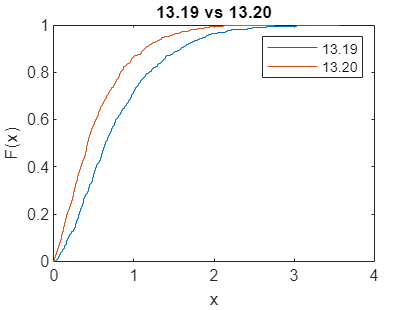

col1 = sistema2(:,1);
col2 = sistema2(:,2);
col3 = sistema2(:,3);
col4 = sistema2(:,4);
col5 = sistema2(:,5);
a1320 = min(col3,min(max(col1,col4),max(col2,col5)));
ecdf(a1320)
title('13.19 vs 13.20')
legend('13.19', '13.20')
hold off

## Punto 25

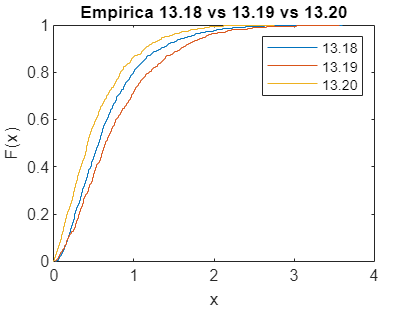

sistema = exprnd(1,1000,6);
col1 = sistema(:,1);
col2 = sistema(:,2);
col3 = sistema(:,3);
col4 = sistema(:,4);
col5 = sistema(:,5);
col6 = sistema(:,6);
a1318 = max(min(col1,col2),min(min(col3,col4),max(col5,col6)));
ecdf(a1318)
hold on
ecdf(a1319)
ecdf(a1320)
title('Empirica 13.18 vs 13.19 vs 13.20')
legend('13.18','13.19', '13.20')
hold off

function [matrix] = robust_product(A,B)
    [rows_a, cols_a] = size(A);
    [~, cols_b]  = size(B);
    robust = zeros(rows_a,cols_b);
    product = zeros(1,cols_a);
    n = cols_a;
    for i = 1:rows_a
        for j = 1:cols_b
            for k = 1:cols_a
                product(1,k) = A(i,k)*B(k,j);
            end
            robust(i,j) = n*median(product);
            product = zeros(1,cols_a);
        end

    end
    matrix = robust;
end
function [emp] = empiric(col)
    n = length(col);
    emp = [];
    for i = 1:length(col)
        ratio = (length(col(col<=col(i))))/n;
        emp = [emp, ratio];
    end

end